contact = rtcontact_MM;
freqSignal = abs(fft(contact));
[pks, locs] = findpeaks(contact);
close;

maxPeakDistance = 350;
filteredLocs = [];
filteredPeaks = [];
for ind = 1:length(locs) -1
    %distance as samplepoints
    distance = locs(ind+1)-locs(ind);
    if distance <= maxPeakDistance
        filteredPeaks = [filteredPeaks, pks(ind)];
        filteredLocs = [filteredLocs, locs(ind)];
    end
end



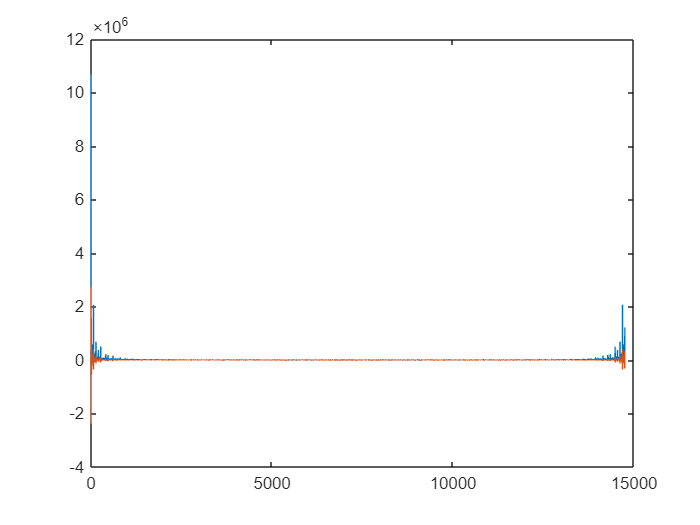

Fs = 200;
T = 1/Fs;

t = linspace(1, length(contact), length(contact)).*T;


filteredFreqSignal = bandpass(freqSignal,[40 60],Fs);

figure;
plot(freqSignal);
hold on;
plot(filteredFreqSignal);
hold off;


tlocs = filteredLocs .*T;

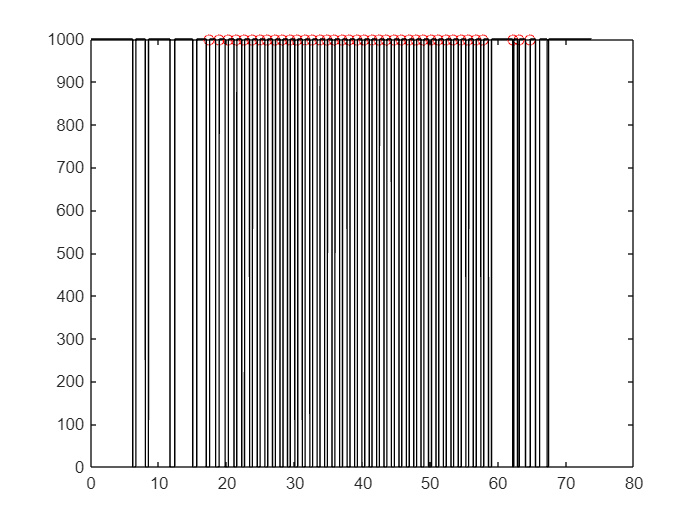

figure;
plot(tlocs, filteredPeaks,'ro');
hold on; 
plot(t, contact,'k');
% plot(,'b');
hold off;